# Examples running MPL

Reference: M. S. Sohail, R. H. Y. Louie, Z. Hong, J. P. Barton, and M. R. MCKay, " Inferring epistasis from genetic time-series data".

These are simple examples of running MPL on time series data from a bi-allelic five-locus system. To run MPL on your data, please see data formatting sections below. 

## Example 1 - Running MPL with replicate combining

The first example shows MPL estimates obtained by combining 5 replicates. For comparison, we compares the replicate combining MPL estimates and their accessibility with those obtaining if the inference is performed on each of the 5 replicates individually.

Note:  Example will not run if the "Analysis" folders already exist. Delete "Analysis" foldersbefore  rerunning this example

## Initialization

These are the user controlled initialization parameters. Data format required by MPL code is explained in sections below. 

priorConstSC = 1; % this is the strength of the selection coefficient regularization parameter
priorConstEpi = 1; % this is the strength of the epistasis terms regularization parameter

numRep = 5; % number of replicates to combine

% specify complete paths to the folder that will contain Data, Analysis, and Results
for i = 1:numRep
    dataDirNameMainCell{i} = ['D:/epistasis-inference-example/Example_Data_' num2str(i) '/'];
    analysisDirNameMainCell{i} = ['D:/epistasis-inference-example/Example_Analysis_' num2str(i) '/'];
    resultsDirNameMainCell{i} = ['D:/epistasis-inference-example/Example_Results_' num2str(i) '/'];


    % this is the filename where the above paths will be stored. This file is
    % located at ...\epistasis-inference-example\Data_Misc\dirNameFiles\
    % This filename should be unique for each dataset being analyzed
    fileNameContainingDirPathCell{i} = ['dirNamesRepCombExample_1_' num2str(i)];
end
dirNameAnalysisRep = ['D:/epistasis-inference-example/Example_Analysis_RepComb_1_5/'];

Lin = 5; % specify the length of the aligned sequence

% specify NT reference sequence
refernceSequence = repmat('A', 1, Lin);


% this is the filename which contains the NT-to-NT mutation probability. It
% must be located in the folder
% ...\epistasis-inference-example\Data_Misc\MutationProbabilities\ 
fileNameContainingMutProb = 'MutProb_SyntheticData_1eminus4.txt';

recombProb = 1e-4; % recombination probability

## Analysis - Repliacte combining

Execute MPL analysis code and performs the following tasks:

- Obtain MPL estimates (replicate combining), and MPL estimates (individual datasets) of selection coefficients and epistasis terms.

- Identify accessible fitness parameters.

- Compute and store mutant allele trajectories from the data.

MPL estimates based on an individual dataset are located in a subfolder named "Estimates" within the corresponding folder specified in analysisDirNameMainCell. Forexample, if the Analysis folder is "D:\epistasis-inference-example\Example_Analysis_1\", then the estimates are located in "D:\epistasis-inference-example\Example_Analysis_1\Estimates\". The file 'SelEstEpi_gammaX_Y.txt'contains the MPL estimates  where X and Y are the user provided numerical values of priorConstSC and priorConstEpi.

MPL estimates based on replicate combining are also located in a subfolder named "Estimates" within the folder specified in dirNameAnalysisRep. 

Format of txt file containing MPL estimates: 

The first Lin entries are the selection coefficients (s_i) while the rest are pairwise epistasis terms (s_ij) in the following order:

s_1   s_2   ...   s_Lin   s_12   s_13   ...   s_1Lin   s_23   s_24   ...   s_2Lin   ...   s_(Lin-1)Lin

Accessible fitness parameters are also located within the the 'Estimates" folder.

Format of txt file containing accessibility:

Total Lin(Lin+1)/2 entries.  1: fitness parameter is accessible   0: fitness parameters in partially/in-accessible

% Analysis
analysisMPL_Epi_v2_rep_outerFunction(priorConstSC, priorConstEpi, recombProb, refernceSequence, ...
    dataDirNameMainCell, analysisDirNameMainCell, resultsDirNameMainCell, fileNameContainingDirPathCell, ...
    fileNameContainingMutProb, Lin, numRep, dirNameAnalysisRep)

Saving .txt file containing names of data and analysis folders...done.
Running preprocessing Step 1 - preparing data files for MPL
-----------------------------------------------------------
Processing file 1 of 11
Using freq: entry of header to find frequency...
Time point 1, sum of frequenices of all haplotypes: 1
Processing file 2 of 11
Using freq: entry of header to find frequency...
Time point 11, sum of frequenices of all haplotypes: 1
Processing file 3 of 11
Using freq: entry of header to find frequency...
Time point 21, sum of frequenices of all haplotypes: 1
Processing file 4 of 11
Using freq: entry of header to find frequency...
Time point 31, sum of frequenices of all haplotypes: 1
Processing file 5 of 11
Using freq: entry of header to find frequency...
Time point 41, sum of frequenices of all haplotypes: 1
Processing file 6 of 11
Using freq: entry of header to find frequency...
Time point 51, sum of frequenices of all haplotypes: 1
Processing file 7 of 11
Using freq: entry 

**Plot MPL replicate combining estimates and comapre with those based on a single dataset**

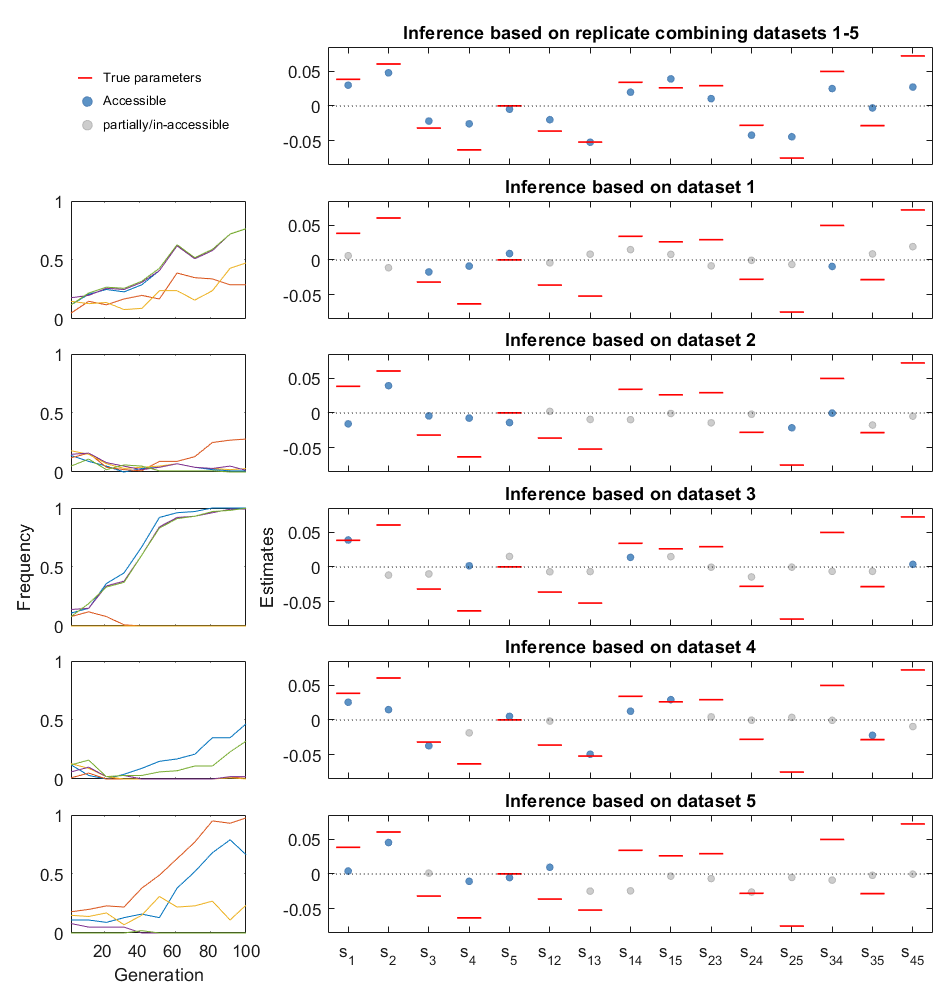

plot_MPL_rep_outerFunction(Lin, numRep, dataDirNameMainCell, analysisDirNameMainCell, dirNameAnalysisRep, priorConstSC, priorConstEpi)

## Example - Running MPL on a single replicate

The second example shows MPL estimates, and their accessibility, obtained from a single dataset (replicate). 

Note:  Example will not run if the "Analysis" folders already exist. Delete "Analysis" foldersbefore  rerunning this example

## Initialization

These are the user controlled initialization parameters.


clc
clear all
close all

%-------------------- USER CONTROLLED INITIALIZATION ----------------------

priorConstSC = 1; % this is the strength of the selection coefficient regularization parameter
priorConstEpi = 1; % this is the strength of the epistasis terms regularization parameter


% specify complete paths to the folder that will contain Data, Analysis, and Results
dataDirNameMain = 'D:/epistasis-inference-example/Example_Data_1/';
analysisDirNameMain = 'D:/epistasis-inference-example/Example_Analysis_1/';
resultsDirNameMain = 'D:/epistasis-inference-example/Example_Results_1/';

% this is the filename where the above paths will be stored. This file is
% located at ...\epistasis-inference-example\Data_Misc\dirNameFiles\
% This filename should be unique for each dataset being analyzed
fileNameContainingDirPathCell{1} = 'dirNamesExample';


Lin = 5; % specify the length of the aligned sequence

% specify NT reference sequence
refernceSequence = repmat('A', 1, Lin);


% this is the filename which contains the NT-to-NT mutation probability. It
% must be located in the folder
% ...\epistasis-inference-example\Data_Misc\MutationProbabilities\ 
fileNameContainingMutProb = 'MutProb_SyntheticData_1eminus4.txt';


recombProb = 1e-4; % recombination probability

## Analysis - Single dataset (replicate)

Execute MPL analysis code and performs the following tasks:

- Obtain MPL estimates of selection coefficients and epistasis terms from a single datasets.

- Identify accessible fitness parameters.

- Compute and store mutant allele trajectories from the data.

MPL estimates based on an individual dataset are located in a subfolder named "Estimates" within the corresponding folder specified in analysisDirNameMainCell. Forexample, if the Analysis folder is "D:\epistasis-inference-example\Example_Analysis_1\", then the estimates are located in "D:\epistasis-inference-example\Example_Analysis_1\Estimates\". The file 'SelEstEpi_gammaX_Y.txt'contains the MPL estimates  where X and Y are the user provided numerical values of priorConstSC and priorConstEpi.

Format of txt file containing MPL estimates: 

The first Lin entries are the selection coefficients (s_i) while the rest are pairwise epistasis terms (s_ij) in the following order:

s_1   s_2   ...   s_Lin   s_12   s_13   ...   s_1Lin   s_23   s_24   ...   s_2Lin   ...   s_(Lin-1)Lin

% Analysis
analysisMPL_Epi_v2_outerFunction(priorConstSC, priorConstEpi, recombProb, refernceSequence, ...
    dataDirNameMain, analysisDirNameMain, resultsDirNameMain, fileNameContainingDirPathCell, ...
    fileNameContainingMutProb, Lin)

Saving .txt file containing names of data and analysis folders...done.
Running preprocessing Step 1 - preparing data files for MPL
-----------------------------------------------------------
Processing file 1 of 11
Using freq: entry of header to find frequency...
Time point 1, sum of frequenices of all haplotypes: 1
Processing file 2 of 11
Using freq: entry of header to find frequency...
Time point 11, sum of frequenices of all haplotypes: 1
Processing file 3 of 11
Using freq: entry of header to find frequency...
Time point 21, sum of frequenices of all haplotypes: 1
Processing file 4 of 11
Using freq: entry of header to find frequency...
Time point 31, sum of frequenices of all haplotypes: 1
Processing file 5 of 11
Using freq: entry of header to find frequency...
Time point 41, sum of frequenices of all haplotypes: 1
Processing file 6 of 11
Using freq: entry of header to find frequency...
Time point 51, sum of frequenices of all haplotypes: 1
Processing file 7 of 11
Using freq: entry 

## **Plot MPL estimates **

The following code displays true and MPL estimates of the fitness parameters

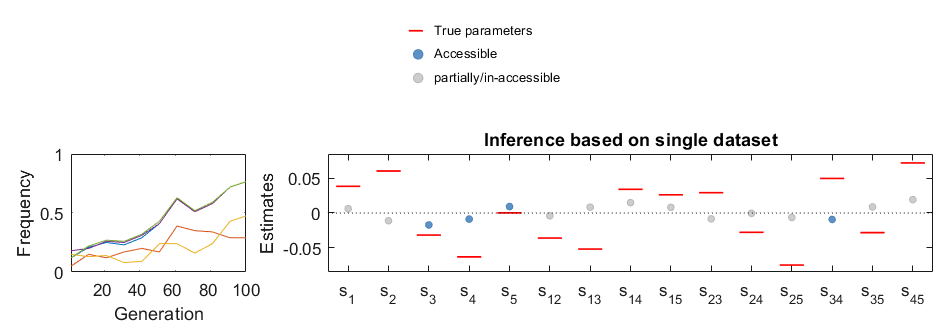

plot_MPL_outerFunction(Lin, {dataDirNameMain}, {analysisDirNameMain}, priorConstSC, priorConstEpi)

## Running MPL on user provided data

This code accepts time series genomic data in the form of fasta format files within a 'Data folder'.  A data folder can contain time series genomic data for a single time series. If you have multiple time series datasets (multiple replicates), each dataset (replicate) shouod be in a separate data folder (see Example 1 above). For each time point, sequences should be in a fasta format file with the following specificiations.  

File name format: File name has to be of the form XY_**_tZ.fasta. here XY could be any alphanumeric text but must not contain special characters. Z must be the absolute time (in generations) of this genetic sample. 

Fasta files: Each fasta file should contain all unique sequences observed at that time point and the reference sequence. All time points must have the same reference sequence. The frequency and count of the sequence should be mentioned in the fasta header as described below. The first sequence in each fasta file should be the reference sequence.

Fasta Header format: All fasta header formats must follow the the structure as shown in the example. The header for the reference sequence must contain the words "reference sequence" The header for all other sequence must be of the format ">haplotype, days: X1, freq: Y1, reads: Z1," Here X1 is the number of generation assocated with this time point. This must match with the time specified in the ffasta filename. All sequences in a file must belong to the same time point. Y1 is the frequency and Z1 is the absolute number of occurances of this sequence at this time point. The frequencies of all sequences occuring at any give time point must sum to 1. The spaces and commas must be exacylu as specified in the example.

Fasta sequence constraints: sequences can contain the following nucleotides: 'ACGT-'. In addition, any locus must not have more than 2 nucleotide alleles at all time points. While the code may execute if any of these conditions is violated, the estimates obtained thus may be erroneous. 

Mutation rate can be specified in a file within the folder ...\epistasis-inference-example\Data_Misc\MutationProbabilities\... See the example mutation probability files provided.